# Seam Carving

Load an image, convert to grey scale, and display it

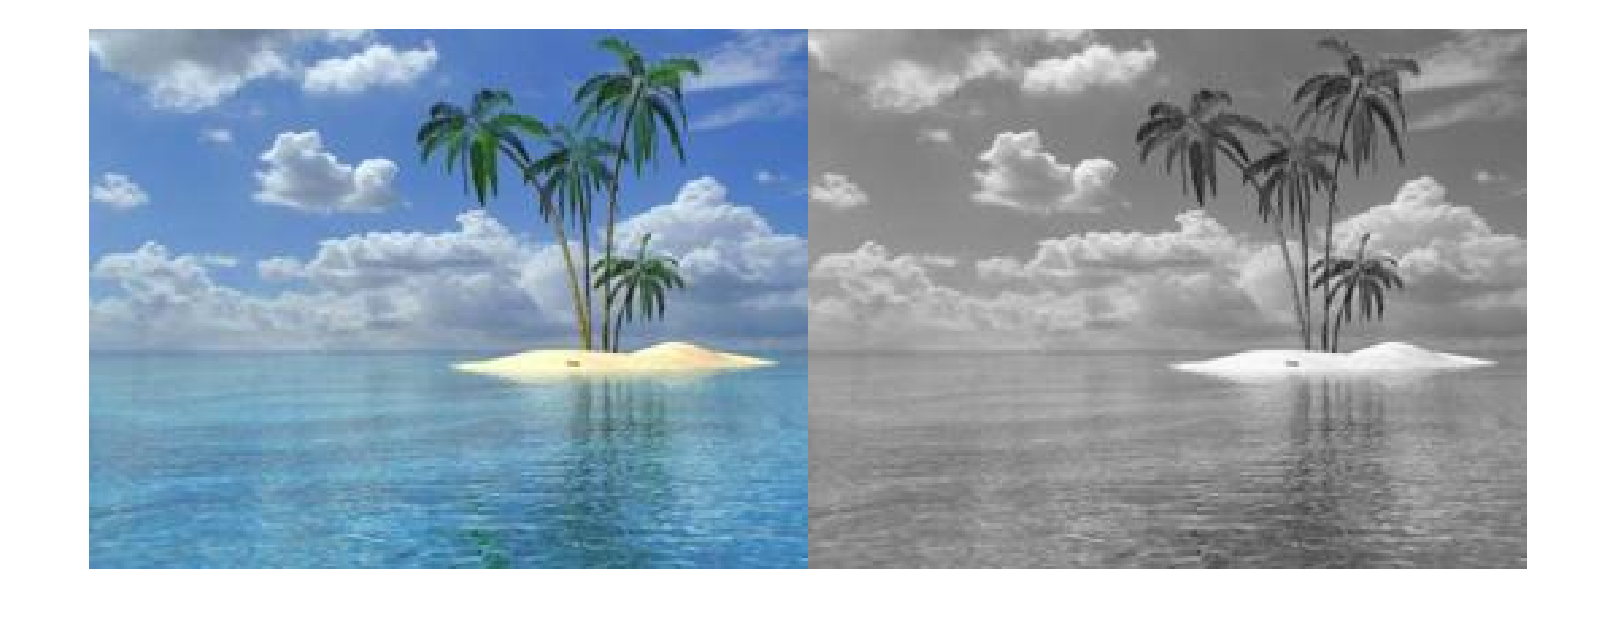

img = imread('ocean_with_trees_smaller.jpg');
grey_img = rgb2gray(img);

montage({img,grey_img});

Find energy matrix and display it as energy image.

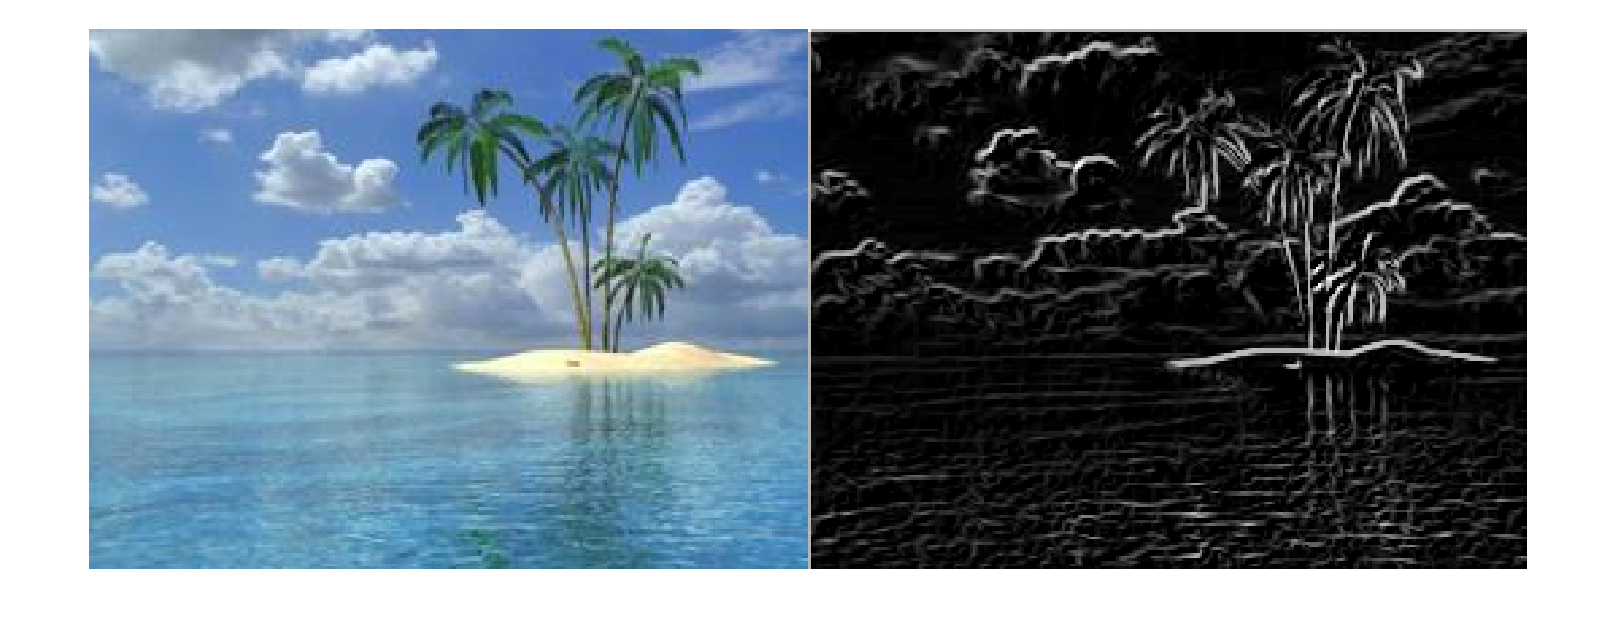

energy_matrix = find_energy(grey_img);

% we need to normalize values in the matrix to find in between 0 and 1, so
% that we can display it properly.
max_value = max(energy_matrix,[],"all");
energy_img = energy_matrix / max_value;

montage({img,energy_img});

Find M matrix (least energy seam) and K matrix (direction)

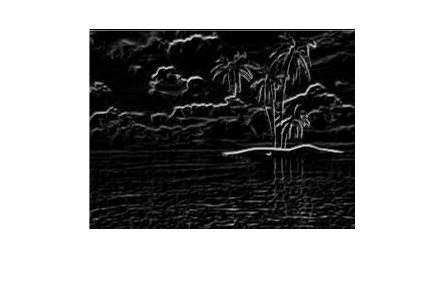

[least_energy,direction] = find_least_energy(energy_matrix);

% we need to normalize values in the matrix to find in between 0 and 1, so
% that we can display it properly.
max_value = max(least_energy,[],"all");
least_energy_img = least_energy / max_value;

imshow(least_energy_img);

Find and display best seam for each column.  We can use the slider to see the best seam for each column interactively.

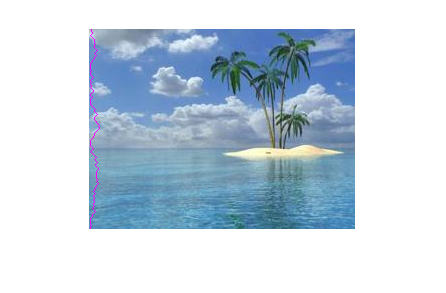

[m,n] = size(grey_img);
[e_min, k_min] = min(least_energy(m,:));

col =2;

path = get_seam_at(direction, col);
marked_img = mark_seam(img, path);

imshow(marked_img);

Remove seam : we can shrink or resize the image to make it small by removing the best seam with the lowest energy.

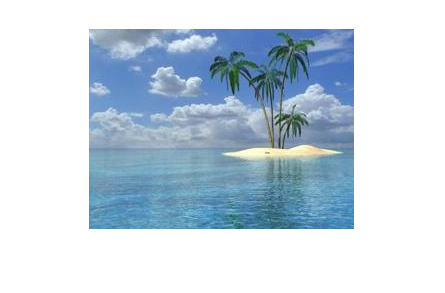

new_img = remove_seam(img, path);

imshow(new_img);

## The code up to this point shows general steps to 

- read image

- calculate the energy

- find the best seam

- remove the seam to shrink the image

### Each time to remove one seam takes time to compute. To make it a bit more interactive, we need to precompute seams and resulting images.  Once we have all resulting images precomputed, we can display it interactively.

### So we need to write code to precompute these results.

## For example, let's assume that we want to shrink our image by half in width (N column), so we can write a function to do all the steps mentioned above and loop N times.

Shrink image : 

n_examples = size(img,2)/2;
%n_examples = 50;

[shrink_imgs,marked_shrink_imgs] = shrink_image(img, n_examples);


Use separate section, so that we can re-play the results faster without having to re-compute again and again.

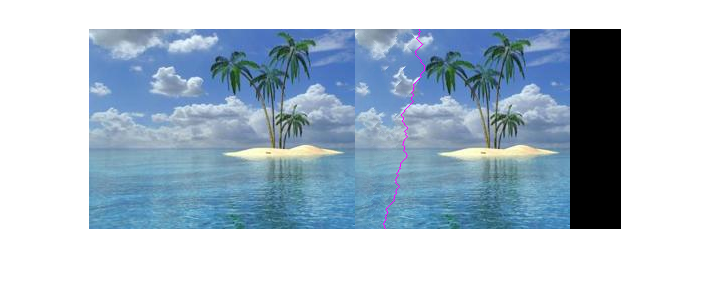

num_to_shrink =52;
%montage({img,cell2mat(marked_shrink_imgs(num_to_shrink))});
imshowpair(img,cell2mat(marked_shrink_imgs(num_to_shrink)),"montage");

# You need to write following functions to make the code above run successfully.

- function energy_matrix = find_energy(grey_img)

- function [least_E, dirs] = find_least_energy(E)

- function path = get_seam_at(dirs, j)

- function marked_img = mark_seam(img, path)

- function new_img = remove_seam(img, path)

- function [shrink_imgs,marked_shrink_imgs] = shrink_image(img, num_to_shrink)

Find energy matrix.  

This function is provided to you to get started. It should work as is.

function energy_matrix = find_energy(grey_img)
    Sx = fspecial('sobel');
    Dx = double(imfilter(grey_img,Sx,'conv'));

    Sy = Sx';
    Dy = double(imfilter(grey_img,Sy,'conv'));

    energy_matrix = sqrt(Dx.^2 + Dy.^2);
end

Compute the M matrix (least_E) and K matrix (dirs). This function compute the M matrix and K matrix as mentioned in the lecture. Note that the direction is changed to -1, 0, 1 instead of 1, 2, 3.

% assumpition: E is 2d array
function [least_E, dirs] = find_least_energy(E)
    [x, y] = size(E);
    least_E = zeros(x, y);
    dirs = zeros(x, y);
    
    least_E(1) = E(1);
    for i = 2 : x
        for j = 1 : y
            if j == 1
                [min_v, min_idx] = min([inf, E(i-1, j), E(i-1, j+1)]);
            elseif j == y
                [min_v, min_idx] = min([E(i-1, j-1), E(i-1, j), inf]);
            else
                [min_v, min_idx] = min([E(i-1, j-1), E(i-1, j), E(i-1, j+1)]);
            end
            
            least_E(i, j) = E(i, j) + min_v;
            dirs(i, j) = min_idx - 2;
        end
    end
    
end

Get seam at a specific column.  This function take a direction matrix and a specified column as input and returns the best seam or path for that column.

function path = get_seam_at(dirs, j)
    [x, ~] = size(dirs);
    path = zeros([x, 2]);
    path(x, 1) = x;
    path(x, 2) = j;
    for i = x-1:-1:1
        j = j + dirs(i, j);
        path(i, 1) = i;
        path(i, 2) = j;
    end
end

Mark seam function take an image and the path or seam as input and return the new marked image that show the seam with some specific color such as [255,0,255].

function marked_img = mark_seam(img, paths)
    marked_img = img;
    [x, ~] = size(img);
    for r = 1:x
        i = paths(r, 1);
        j = paths(r, 2);
        marked_img(i, j, 1) = 255;
        marked_img(i, j, 2) = 0;
        marked_img(i, j, 3) = 255;
    end
end

Remove seam from image (one column less).  This function take an image and seam as input, and output a new image with one column less than before.

function new_img = remove_seam(img, path)
    [w, h, c] = size(img);
    new_img = zeros([w, h-1, c], "uint8");
    for i = 1:w
        count = 1;
        for j = 1:h
            if path(i, 2) ~= j
                new_img(i, count, :) = img(i, j, :);
                count = count + 1;
            end
        end
    end
end

Shrink image function takes an image and number of columns to shrink.  It precomputes the images from removed each seam one by one. It returns two cell arrays of images with different sizes so we can display interactively later on.

function [shrink_imgs, marked_shrink_imgs] = shrink_image(img, num_to_shrink)
    
    %shrink_imgs = zeros([num_to_shrink, w, h, c], "uint8");
    %marked_shrink_imgs = zeros([num_to_shrink, w, h, c], "uint8");
    shrink_imgs = cell(num_to_shrink);
    marked_shrink_imgs = cell(num_to_shrink);
    for n = 1:num_to_shrink
        if n == 1
            grey_img = rgb2gray(img);
        else
            grey_img = rgb2gray(squeeze(shrink_imgs{n-1}));
        end
        energy_matrix = find_energy(grey_img);
        [least_energy, direction] = find_least_energy(energy_matrix);
        [m, ~] = size(grey_img);
        [~, col] = min(least_energy(m,:));
        paths = get_seam_at(direction, col);
        if n == 1
            marked_img = mark_seam(img, paths);
            marked_shrink_imgs{n} = marked_img;
            shrinked = remove_seam(img, paths);
            shrink_imgs{n} = shrinked;
        else
            marked_img = mark_seam(shrink_imgs{n-1}, paths);
            marked_shrink_imgs{n} = marked_img;
            shrinked = remove_seam(shrink_imgs{n-1}, paths);
            shrink_imgs{n} = shrinked;
        end
    end
end